**Extension: Analyzing the effects of learning rate**

**Summary:**

In this extension, the goal was to analyze what the correlation between categories, plots, learning rates, and epochs would be. I take a step by step analysis of decreasing learning rate coupled with increased number of epochs. In the end, several things can be learned. First, as learning rate decreases, there appears to be an increase in number of categories/granularity of categories. Our initial plot with a beta of 1 had 3 categorie boxes and a rather abysmal accuracy. By the time we had a learning rate of .01, we were dealing with about 15 category boxes. This granularity increased accuracy, especially in the .25 -> .5 learning rate range. Another thing I was able to gather from doing this was that there was growth in boxes as they became more established. This was noticeable in the increased number of epochs. For example, when we increased from 3 epochs -> 10 epochs at a learning rate of .5, the boxes didn't change much, they mostly grew. This was theorized in class, but placed in reality here. Increasing the number of epochs really strengthens the boxes. Overall, if I were going to do training with unlimited time, I would use a lower learning rate of .25 or below and increase the number of epochs. The granularity gained in category boxes is key for increasing accuracy. 

**Data and Analysis:**

We first need to establish the training capabilities with a learning rate of 1 and a single epoch.

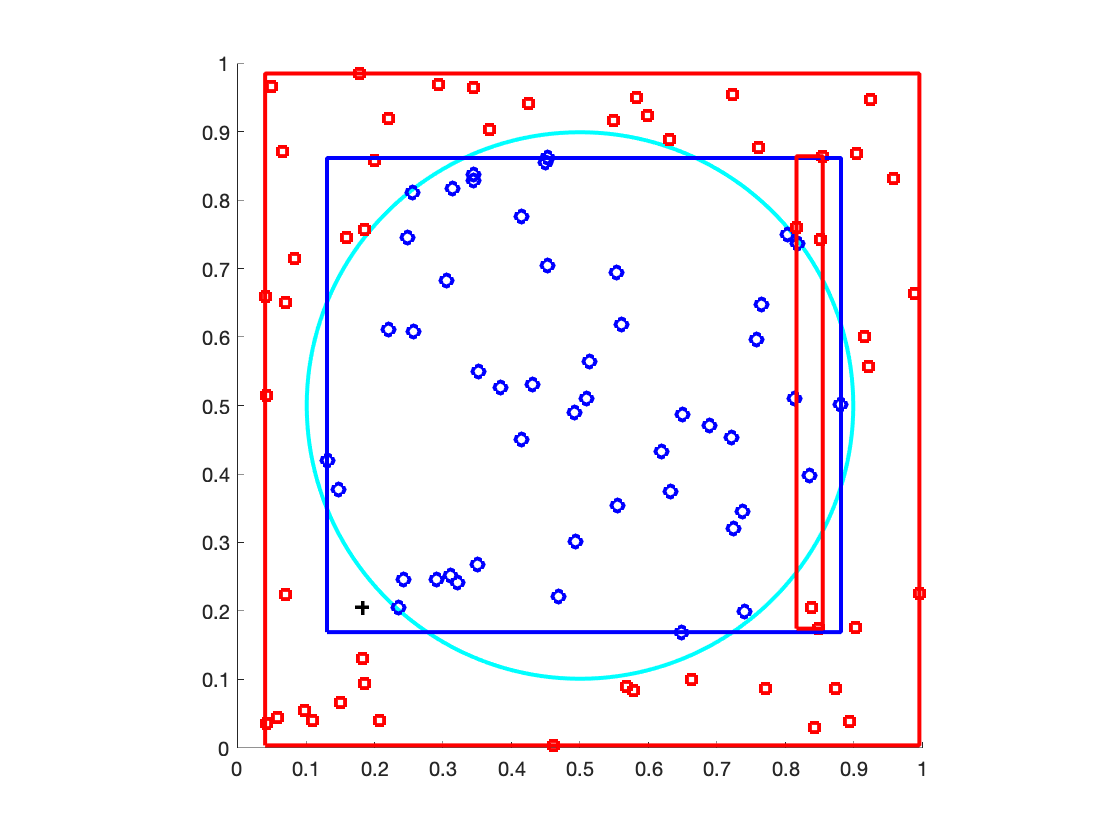

data_x = load("data/cis_x_100.mat");
data_y = load("data/cis_y_100.mat");

data_x = struct2array(data_x);
data_y = struct2array(data_y);

[C, w_code, w_out] = artmap_train(data_x, data_y,2,1,1 );

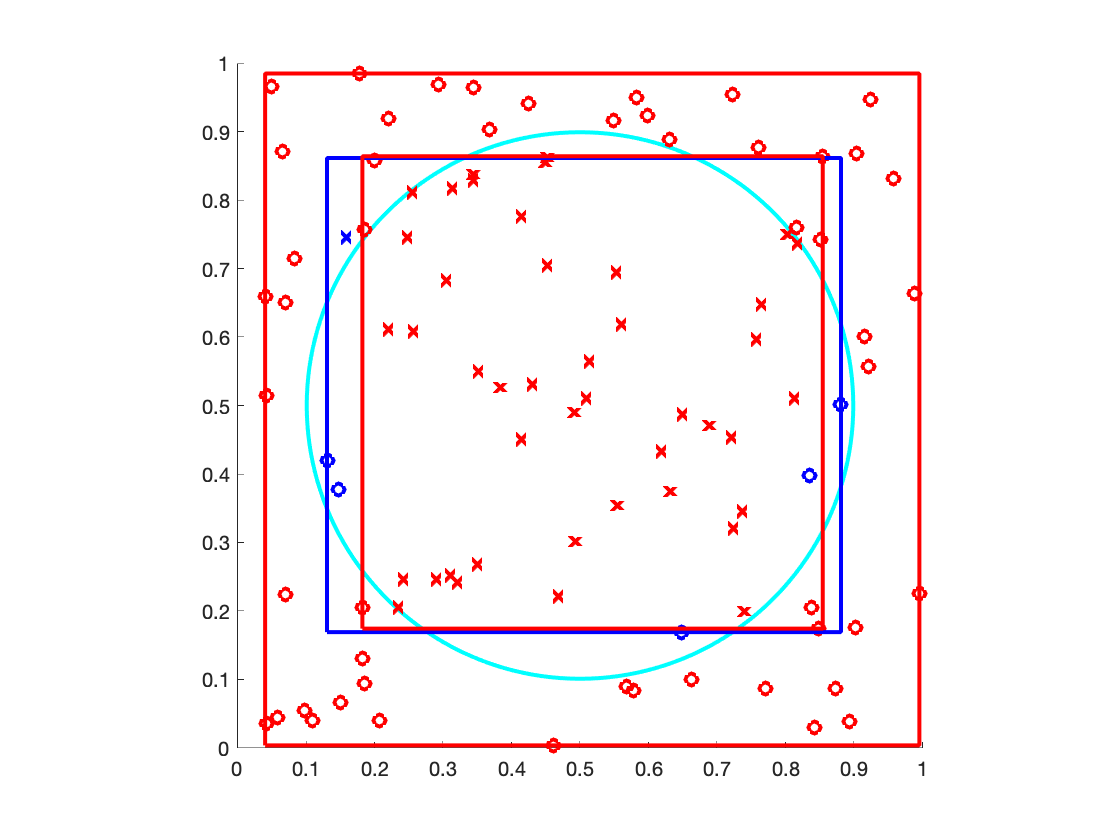

ypred_h =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     0     1     1     1     1     0     1     1     1     1     1     1     1     1     1


ypred_h = artmap_test_wta(C, w_code, w_out, data_x, data_y, 2, 0, 1)

We appear to have a ton of misses inside the tests with the fast learning rate because one of our red boxes classifies everything inside as a square.

Beta: .5 | Epoch: 1

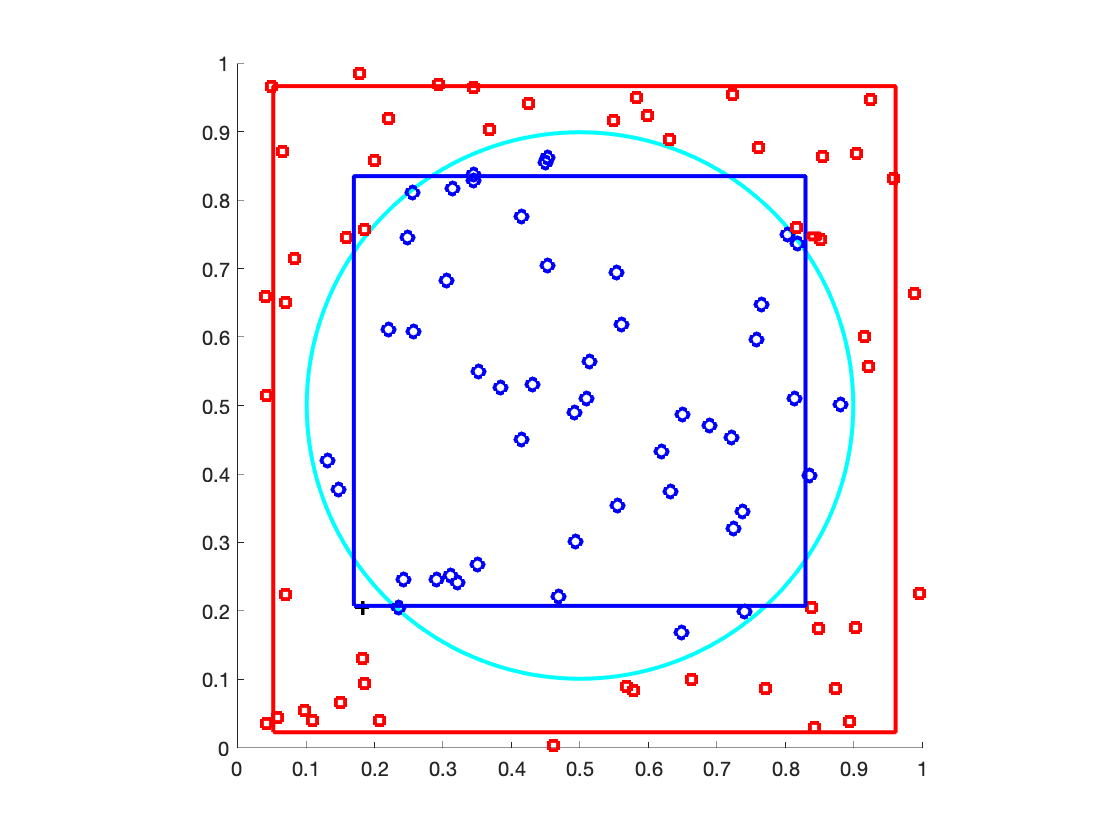

[C, w_code, w_out] = artmap_train(data_x, data_y,2,1,1 );

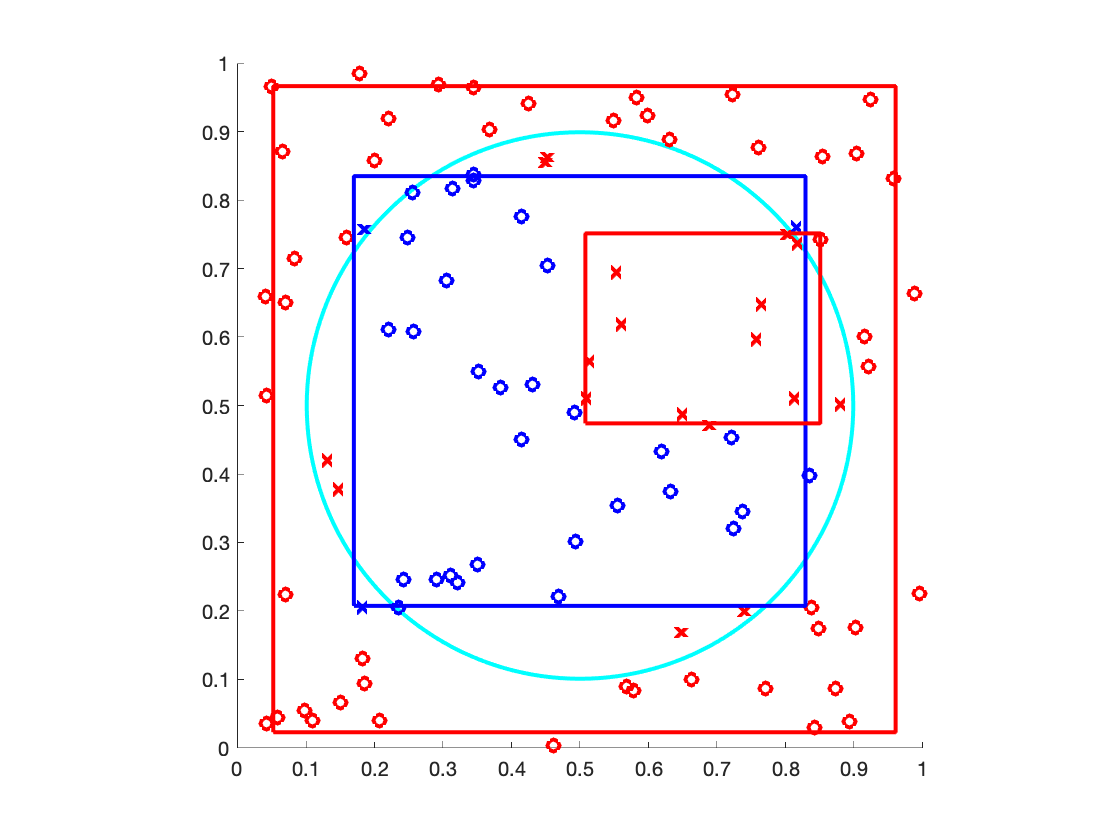

ypred_h =      0     0     0     1     0     0     0     0     0     0     0     0     1     1     1     0     0     0     1     0     0     1     0     1     1     1     1     0     0     1     1     1     0     0     0     0     1     0     0     1     0     1     0     1     1     0     1     0     1     0
     0     1     1     0     1     1     1     1     1     1     1     1     0     0     0     1     1     1     0     1     1     0     1     0     0     0     0     1     1     0     0     0     1     1     1     1     0     1     1     0     1     0     1     0     0     1     0     1     0     1


ypred_h = artmap_test_wta(C, w_code, w_out, data_x, data_y, 2, 0, 1)

It is interesting to see the adjustment of the category boxes. In training, it seems to create only one internal blue box and one large red box. In test, it misses several classifications. It designates a grouping of red on the right side that are mis-classified as squares inside the circle as well as several circles that should be in the squares.

Beta: .25 | Epoch: 1

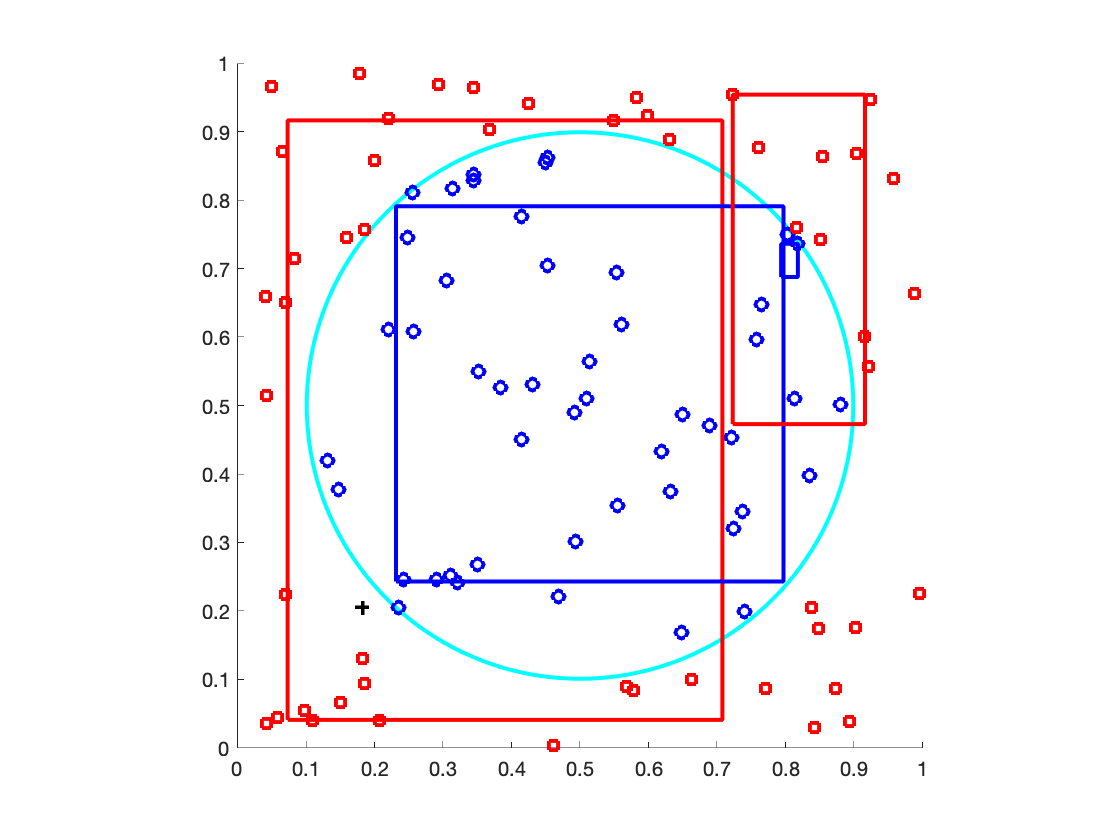

[C, w_code, w_out] = artmap_train(data_x, data_y,2,1,1 );

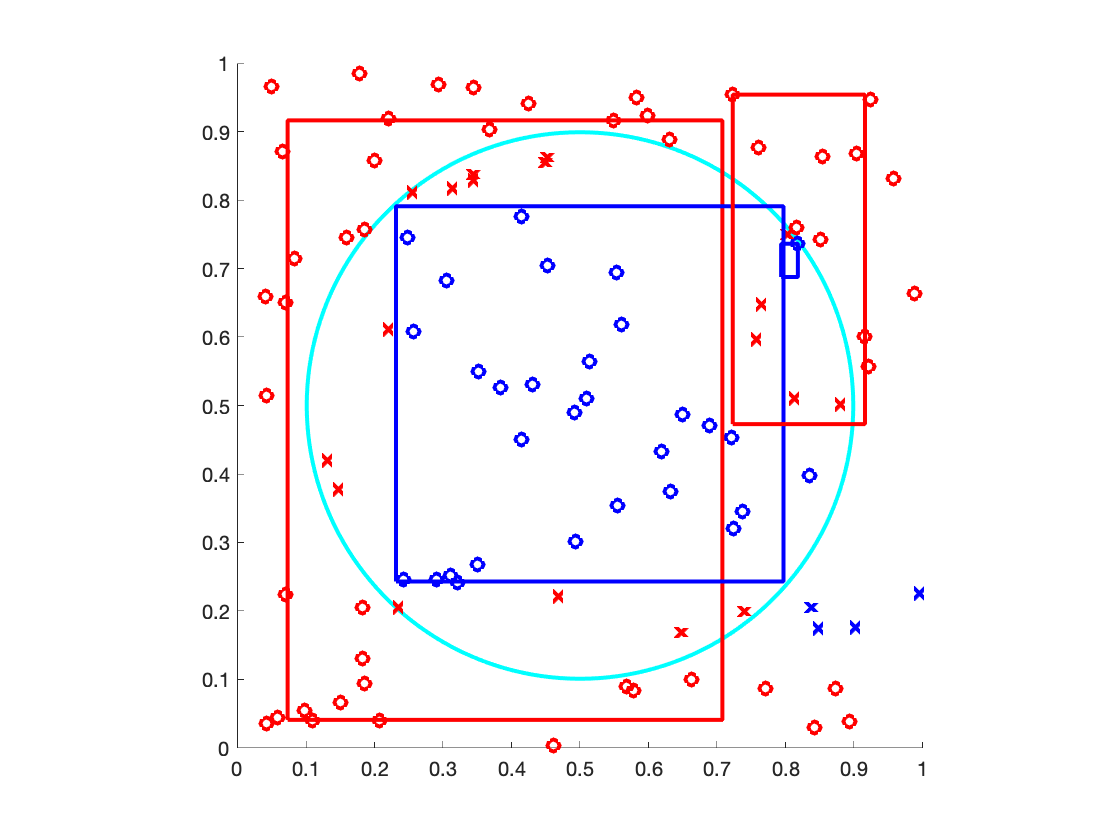

ypred_h =      0     0     0     1     0     0     0     0     0     0     0     0     1     1     0     0     0     1     1     0     1     0     0     1     1     1     0     0     0     1     1     1     0     0     0     0     0     0     0     1     0     1     0     1     1     0     0     0     1     0
     0     1     1     0     1     1     1     1     1     1     1     1     0     0     1     1     1     0     0     1     0     1     1     0     0     0     1     1     1     0     0     0     1     1     1     1     1     1     1     0     1     0     1     0     0     1     1     1     0     1


ypred_h = artmap_test_wta(C, w_code, w_out, data_x, data_y, 2, 0, 1)

As learning rate decreases, we see more misses and poorly defined category boxes. Something to notice here is the size of a category box, where a category box is supposed to grow as it becomes more established. These category boxes with a learning rate of .25 are much smaller than the category boxes with a fast learning rate of 1. This also leads to more misses in the categories.

Beta: .1 | Epoch: 1

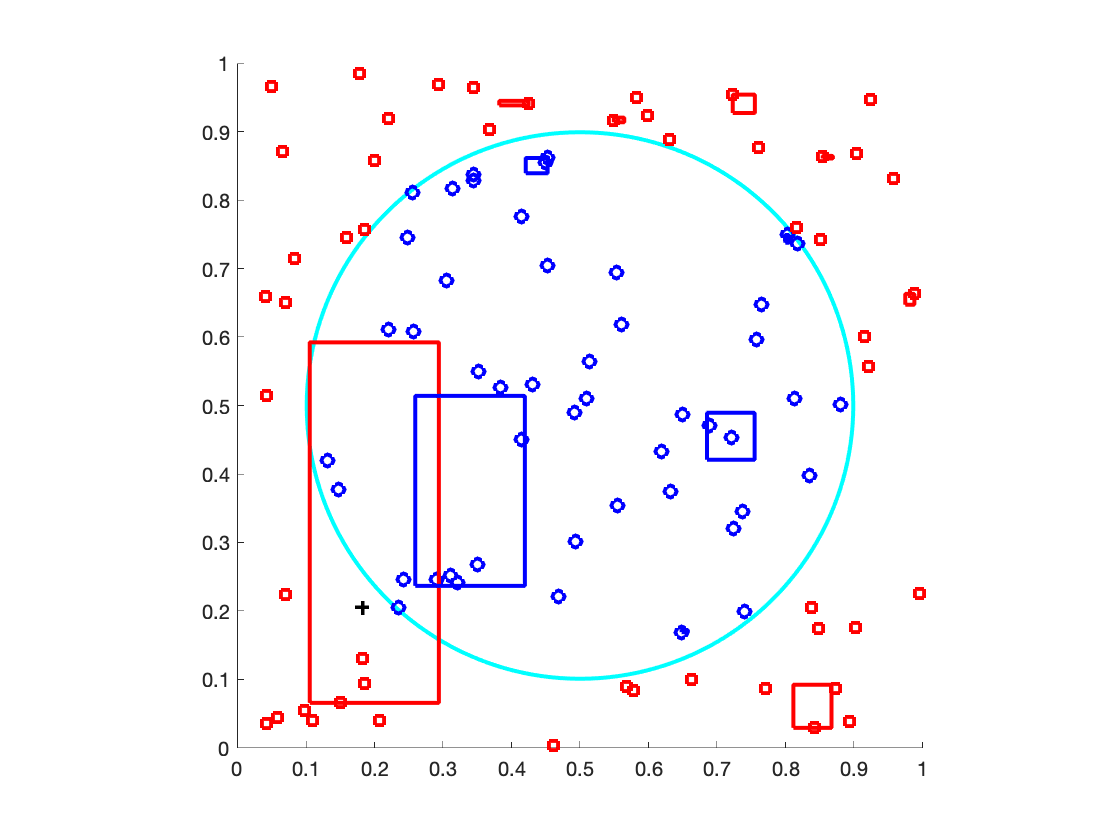

[C, w_code, w_out] = artmap_train(data_x, data_y,2,1,1 );

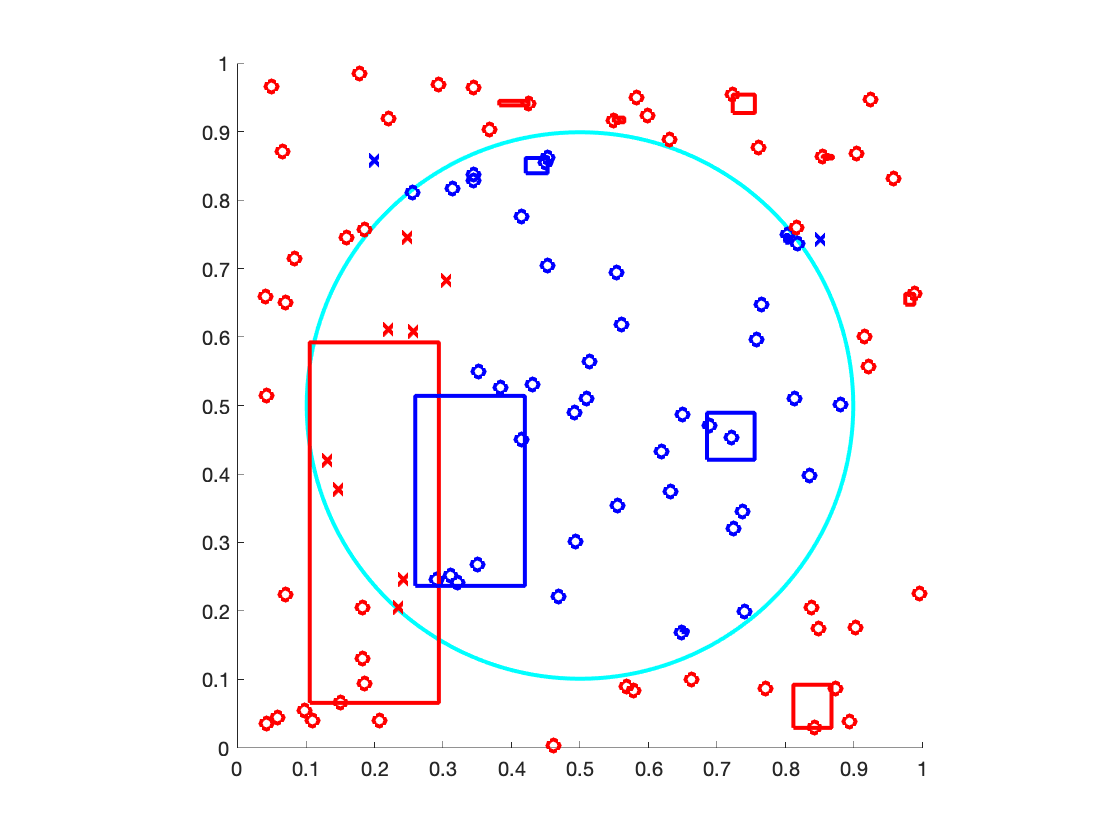

ypred_h =      0     0     0     1     0     0     0     1     0     0     0     0     1     0     1     0     0     0     0     0     1     0     1     1     1     1     1     1     0     1     0     1     0     1     1     0     0     0     1     1     1     1     0     0     1     0     1     0     1     0
     0     1     1     0     1     1     1     0     1     1     1     1     0     1     0     1     1     1     1     1     0     1     0     0     0     0     0     0     1     0     1     0     1     0     0     1     1     1     0     0     0     0     1     1     0     1     0     1     0     1


ypred_h = artmap_test_wta(C, w_code, w_out, data_x, data_y, 2, 0, 1)

Again, we are a magnitude slower now and the boxes are looking far worse. We have a handful of smaller category boxes, none of which are encapsulating many points. This is leading to a high number of accuracy misses, though not as many as one might expect. It is interesting to see there are still generally a majority of items within the circle that are classified as circles and visa versa.

Beta: .01 | Epoch: 1

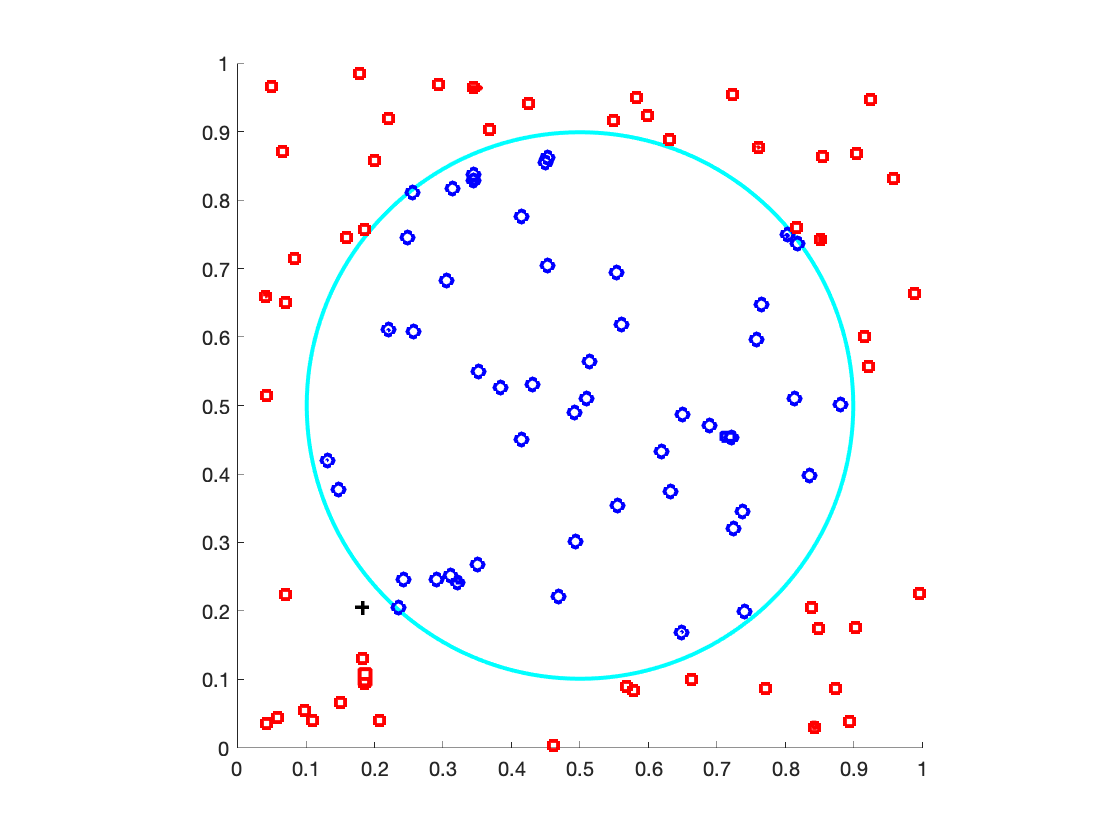

[C, w_code, w_out] = artmap_train(data_x, data_y,2,1,1 );

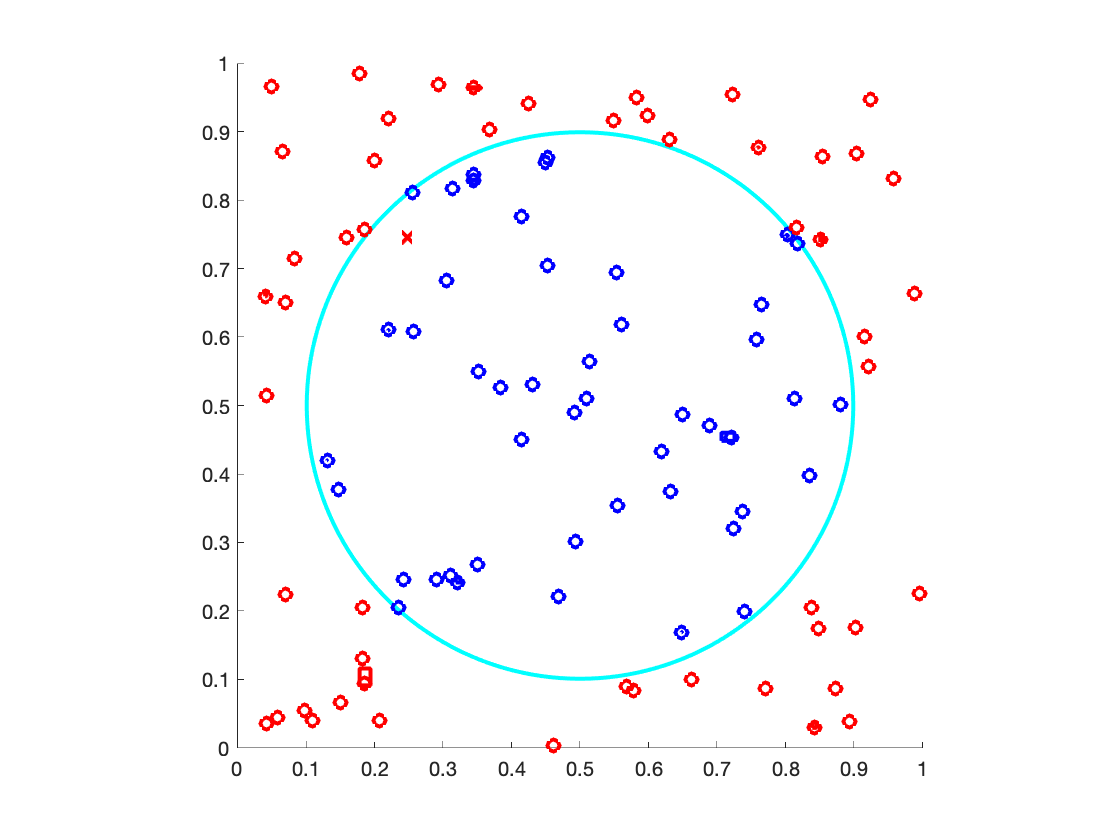

ypred_h =      0     0     0     1     0     0     0     0     0     0     0     0     1     1     1     0     0     0     1     0     1     1     1     1     1     1     1     1     0     1     0     1     0     1     0     0     0     0     1     1     1     1     0     1     1     0     1     0     1     0
     0     1     1     0     1     1     1     1     1     1     1     1     0     0     0     1     1     1     0     1     0     0     0     0     0     0     0     0     1     0     1     0     1     0     1     1     1     1     0     0     0     0     1     0     0     1     0     1     0     1


ypred_h = artmap_test_wta(C, w_code, w_out, data_x, data_y, 2, 0, 1)

We are now dealing with an absolution of boxes, but high accuracy. As there are no category boxes established here yet, it seems impossible to actually classify this. It is curious that there were so few misses involved. I hypothesize that this is a result of there being a single accurate pass, or prelabelled data.

Beta: .001 | Epoch: 1

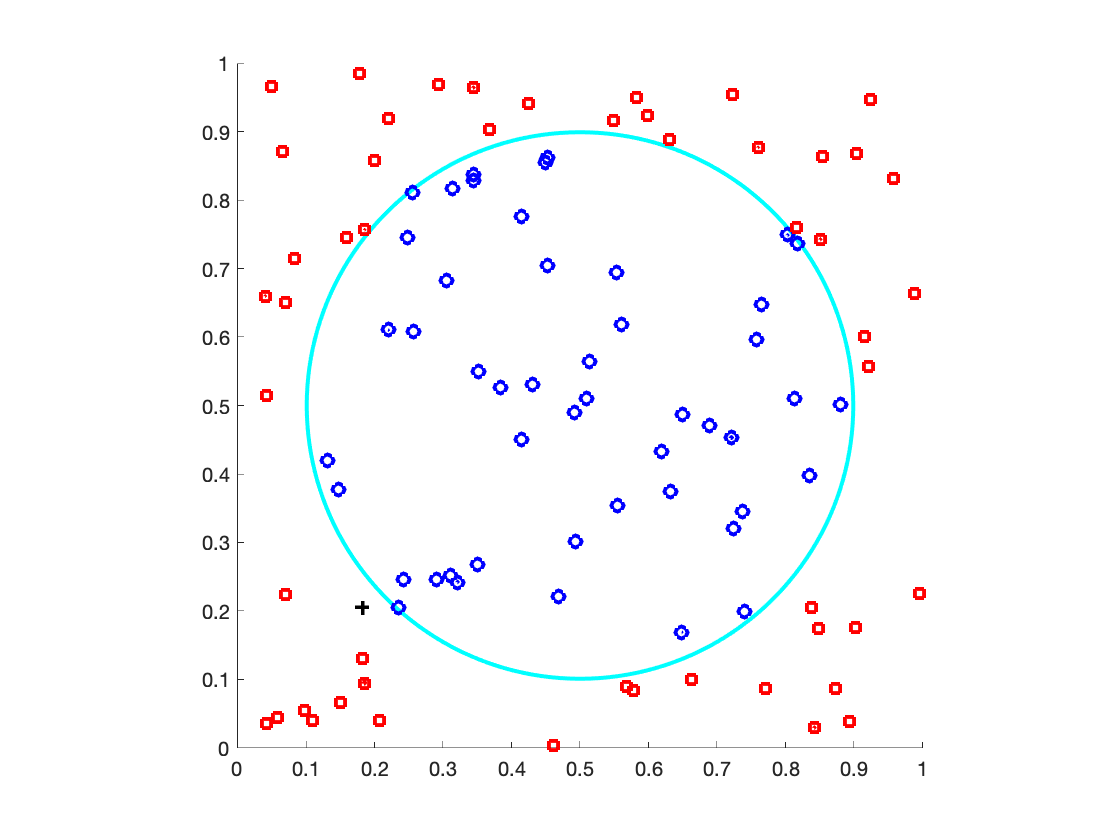

[C, w_code, w_out] = artmap_train(data_x, data_y,2,1,1 );

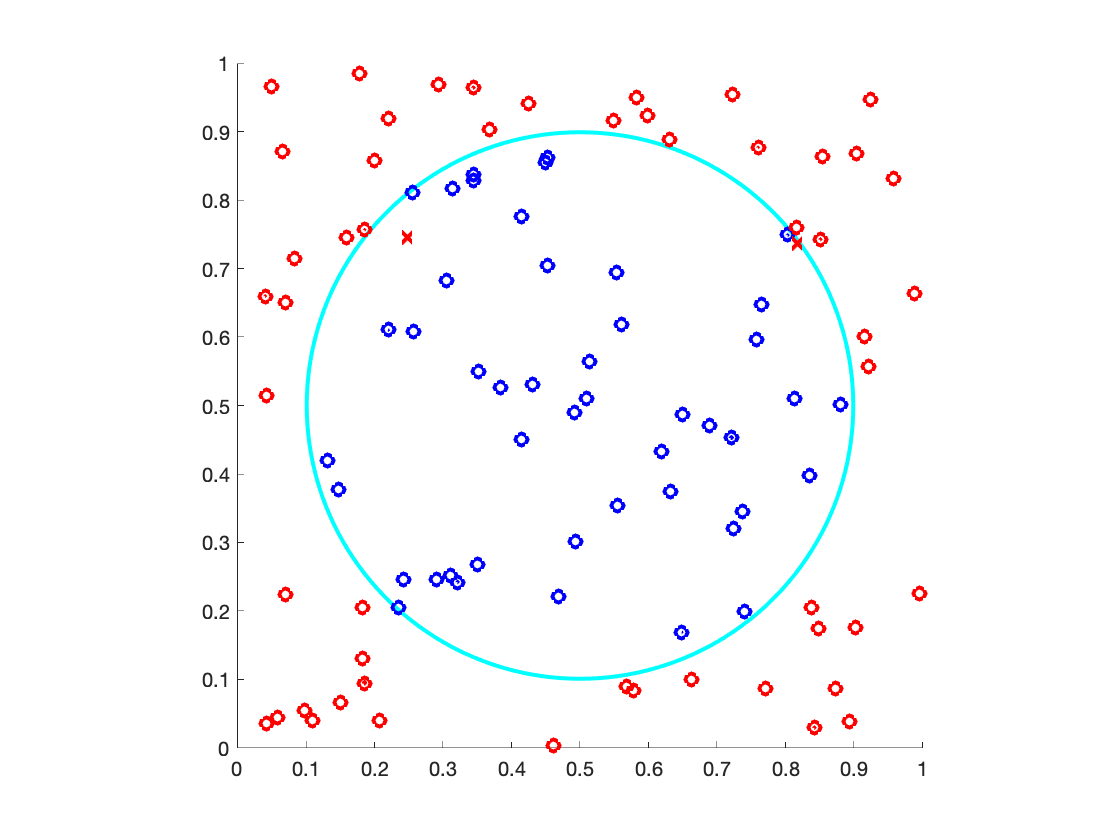

ypred_h =      0     0     0     1     0     0     0     0     0     0     0     0     1     1     1     0     0     0     1     0     1     1     1     1     1     1     1     1     0     1     0     1     0     1     0     0     0     0     1     1     1     1     0     1     1     0     1     0     1     0
     0     1     1     0     1     1     1     1     1     1     1     1     0     0     0     1     1     1     0     1     0     0     0     0     0     0     0     0     1     0     1     0     1     0     1     1     1     1     0     0     0     0     1     0     0     1     0     1     0     1


ypred_h = artmap_test_wta(C, w_code, w_out, data_x, data_y, 2, 0, 1)

This is a hyperbolic hyperparameter, here to provide the extreme representation of what could be. Again, we have no established category boxes as we learn at 1000th the pace that fast learning learns. 

Beta: .5 | Epoch: 3

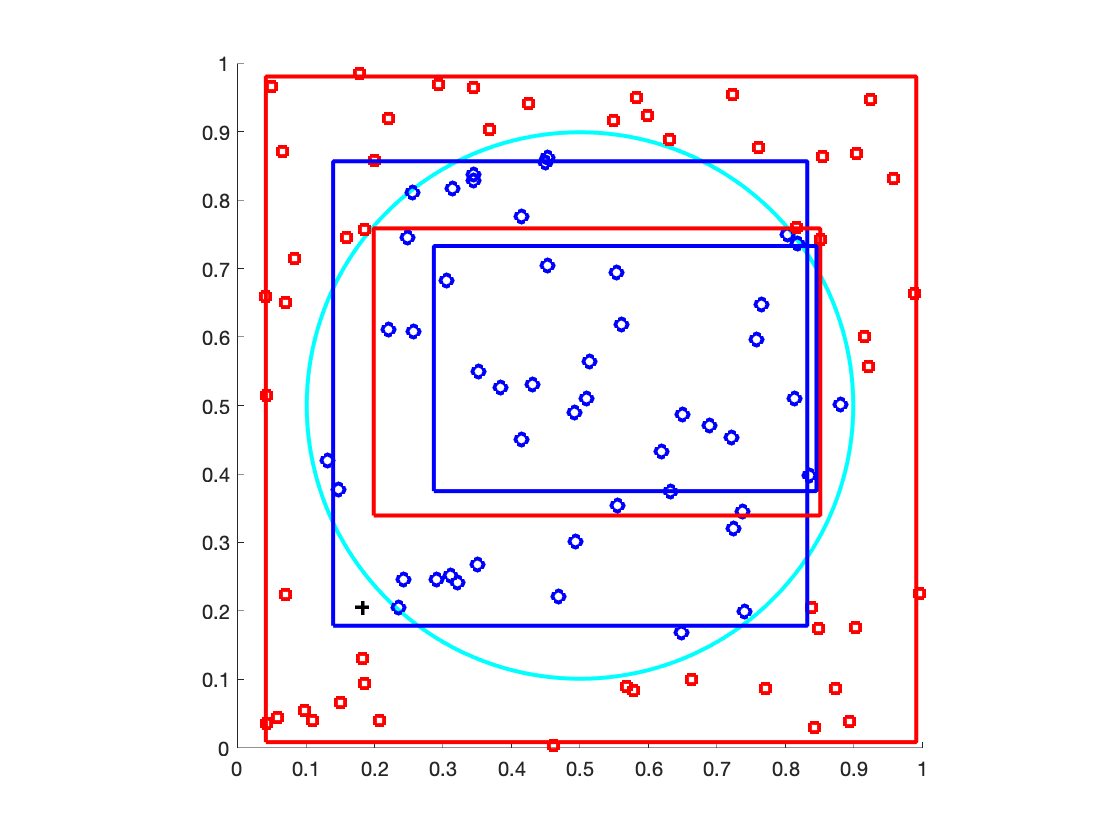

[C, w_code, w_out] = artmap_train(data_x, data_y,2,1,1 );

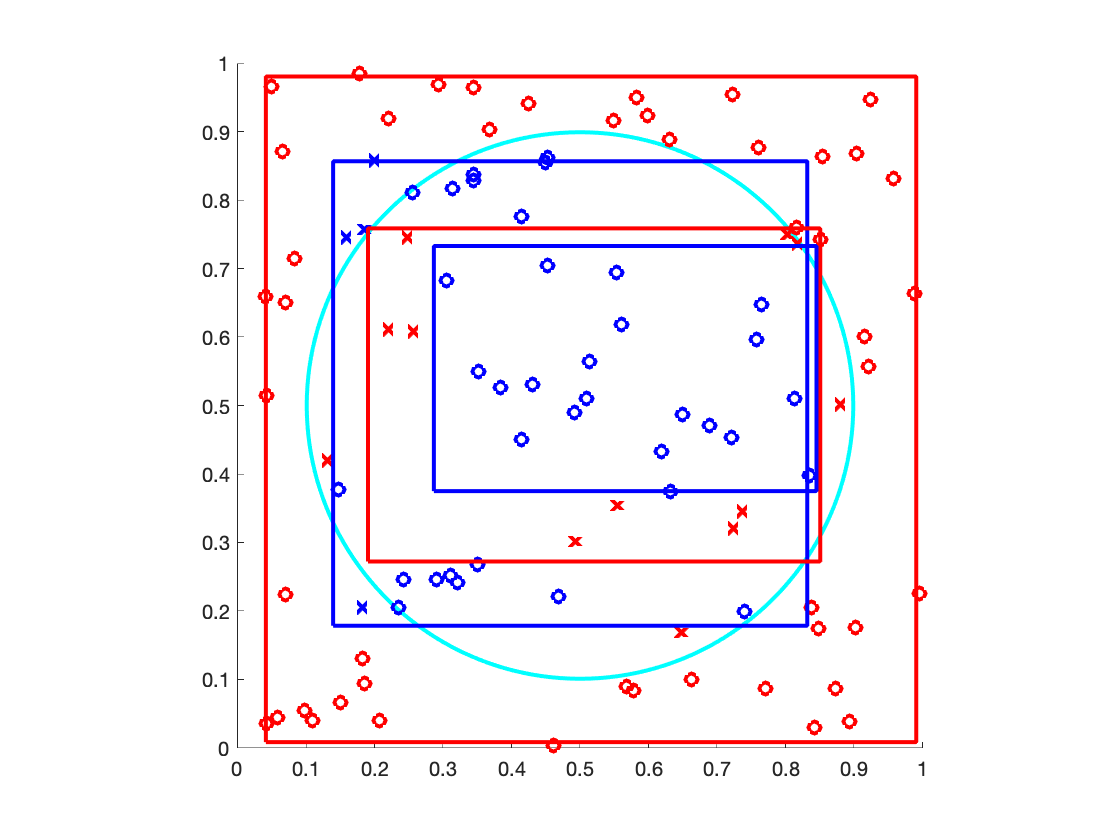

ypred_h =      0     0     0     1     0     0     0     1     0     0     0     0     1     0     1     0     0     0     1     0     1     1     1     0     1     0     1     0     0     1     0     0     0     1     0     1     1     0     0     1     0     1     0     1     1     0     1     0     1     0
     0     1     1     0     1     1     1     0     1     1     1     1     0     1     0     1     1     1     0     1     0     0     0     1     0     1     0     1     1     0     1     1     1     0     1     0     0     1     1     0     1     0     1     0     0     1     0     1     0     1


ypred_h = artmap_test_wta(C, w_code, w_out, data_x, data_y, 2, 0, 1)

This is where we start to increase the number of epochs to help adjust to the learning rate. We can take notice of the increased number of boxes as well as box size. Our classification ends up semi accurate here. We have a lot of misses with the internal red box that exists inside the circle, but the blue boxes still hold the majority in the circle. This is a better accuracy than our first fast learning and has larger and well established category boxes. However, we do trade for time here as this takes somewhat longer to train. 

Beta: .25 | Epoch: 3

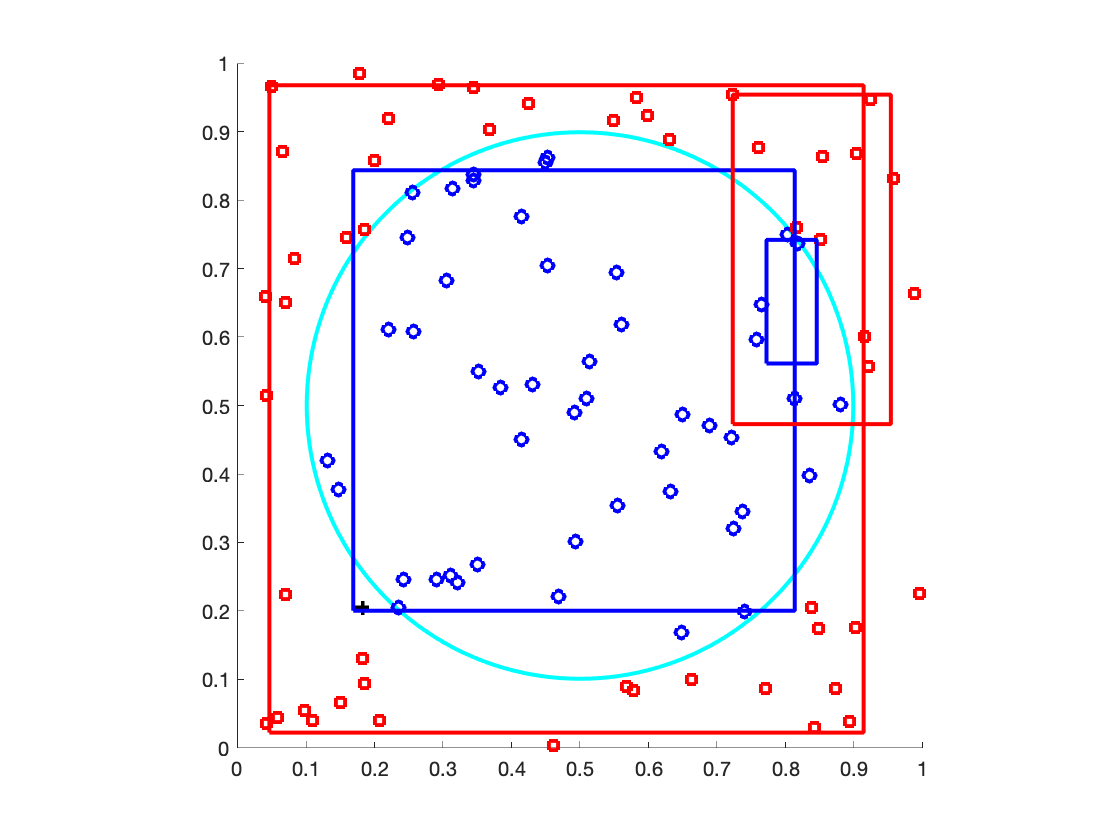

[C, w_code, w_out] = artmap_train(data_x, data_y,2,1,1 );

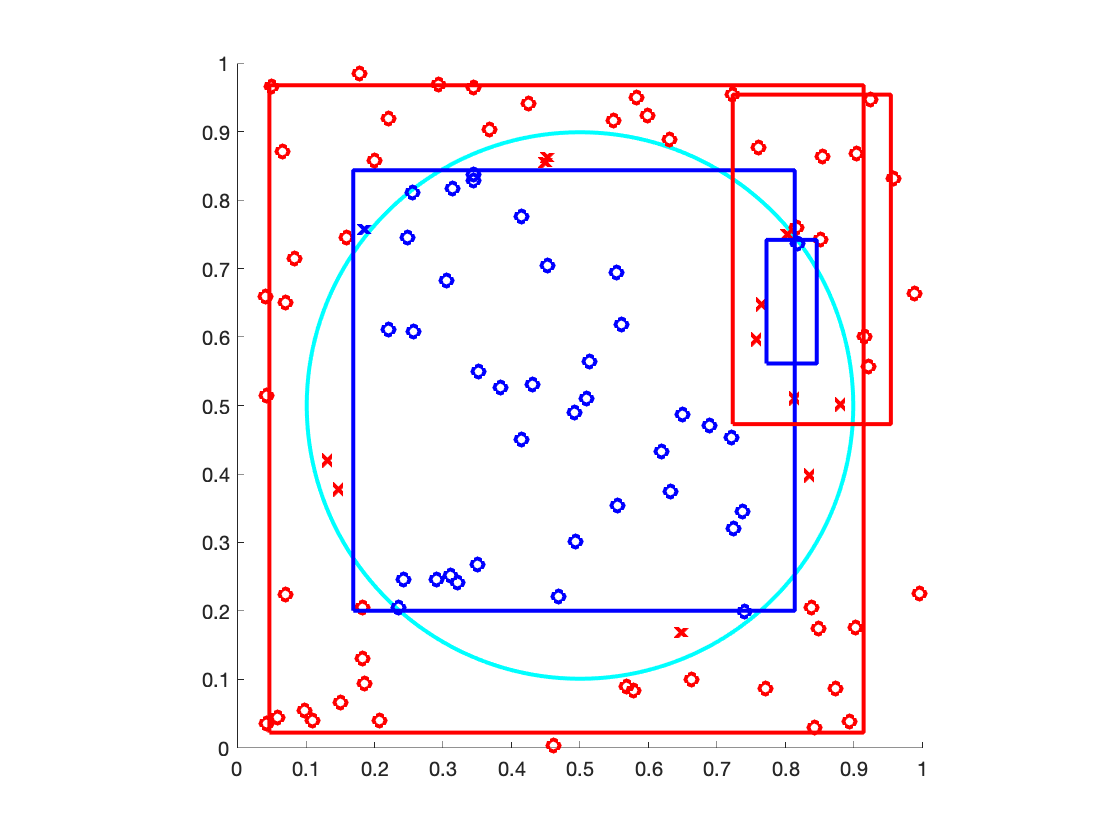

ypred_h =      0     0     0     1     0     0     0     0     0     0     0     0     1     1     1     0     0     0     1     0     1     1     0     1     1     1     1     0     0     1     1     1     0     0     0     0     1     0     0     1     0     1     0     1     1     0     1     0     1     0
     0     1     1     0     1     1     1     1     1     1     1     1     0     0     0     1     1     1     0     1     0     0     1     0     0     0     0     1     1     0     0     0     1     1     1     1     0     1     1     0     1     0     1     0     0     1     0     1     0     1


ypred_h = artmap_test_wta(C, w_code, w_out, data_x, data_y, 2, 0, 1)

This actually provides really good accuracy. There are two well-established category boxes, one in the ground truth circle as well as one well established representing squares outside the circle. Then in the top right we have several more squares but they generally align well with the categories they represent. The smaller square is blue and exists mostly inside the circle while the larger red square is outside the circle. Overall, solid representation of accuracy. 

Beta: .01 | Epoch: 3

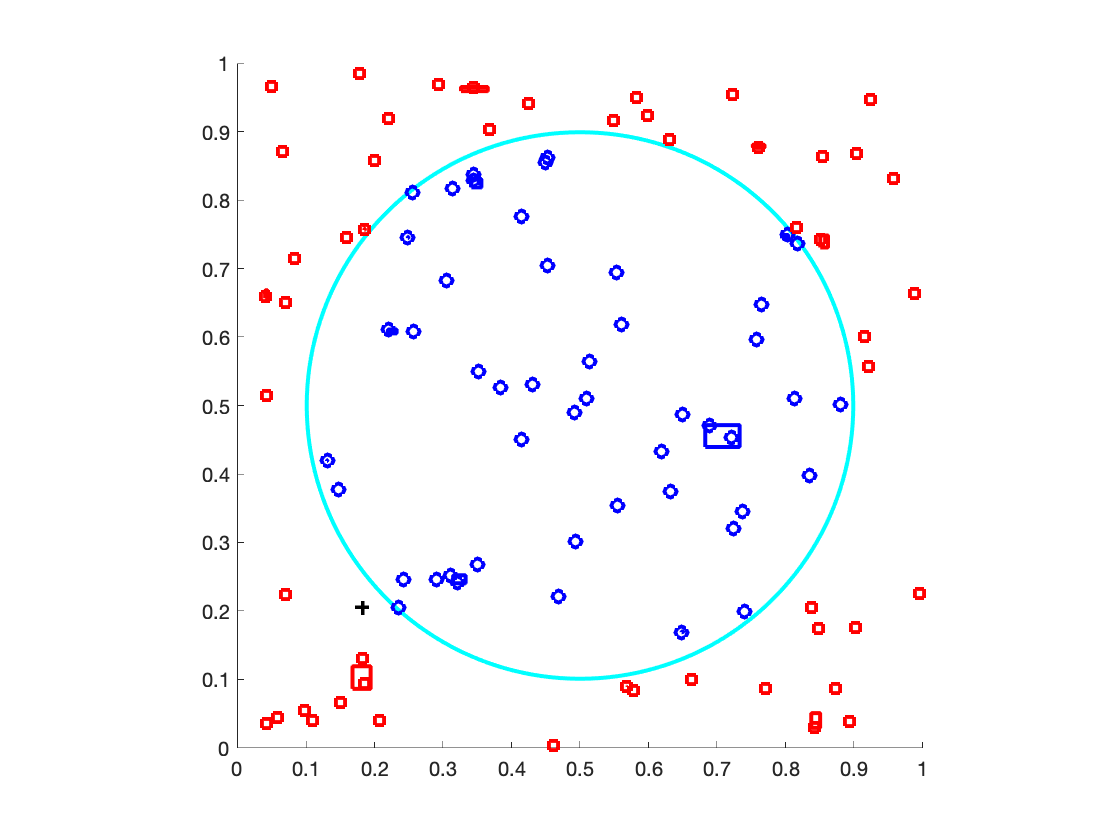

[C, w_code, w_out] = artmap_train(data_x, data_y,2,1,1 );

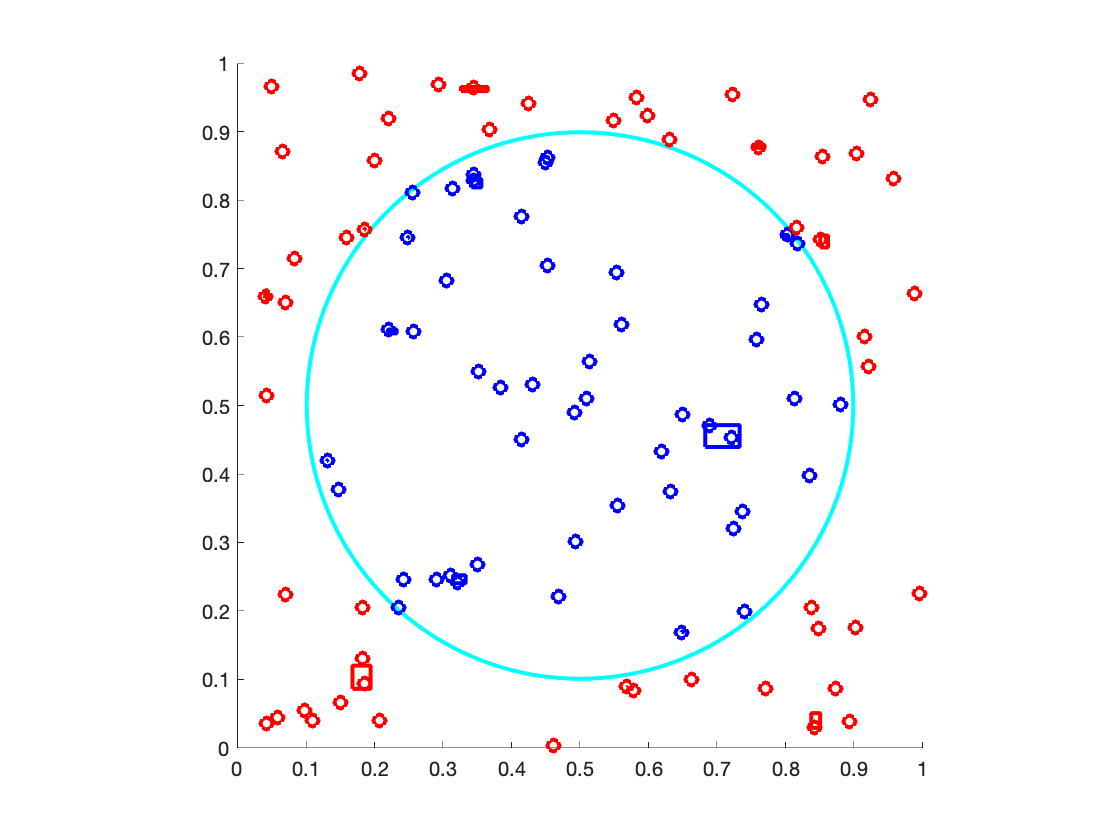

ypred_h =      0     0     0     1     0     0     0     0     0     0     0     0     1     1     1     0     0     0     1     0     1     1     1     1     1     1     1     1     0     1     1     1     0     1     0     0     0     0     1     1     1     1     0     1     1     0     1     0     1     0
     0     1     1     0     1     1     1     1     1     1     1     1     0     0     0     1     1     1     0     1     0     0     0     0     0     0     0     0     1     0     0     0     1     0     1     1     1     1     0     0     0     0     1     0     0     1     0     1     0     1


ypred_h = artmap_test_wta(C, w_code, w_out, data_x, data_y, 2, 0, 1)

We can see the basic formation of category boxes here, but still at a small learning rate 1/100th of the speed of fast learning, we are unable to learn all that much. 

Beta: .5 | Epoch: 10

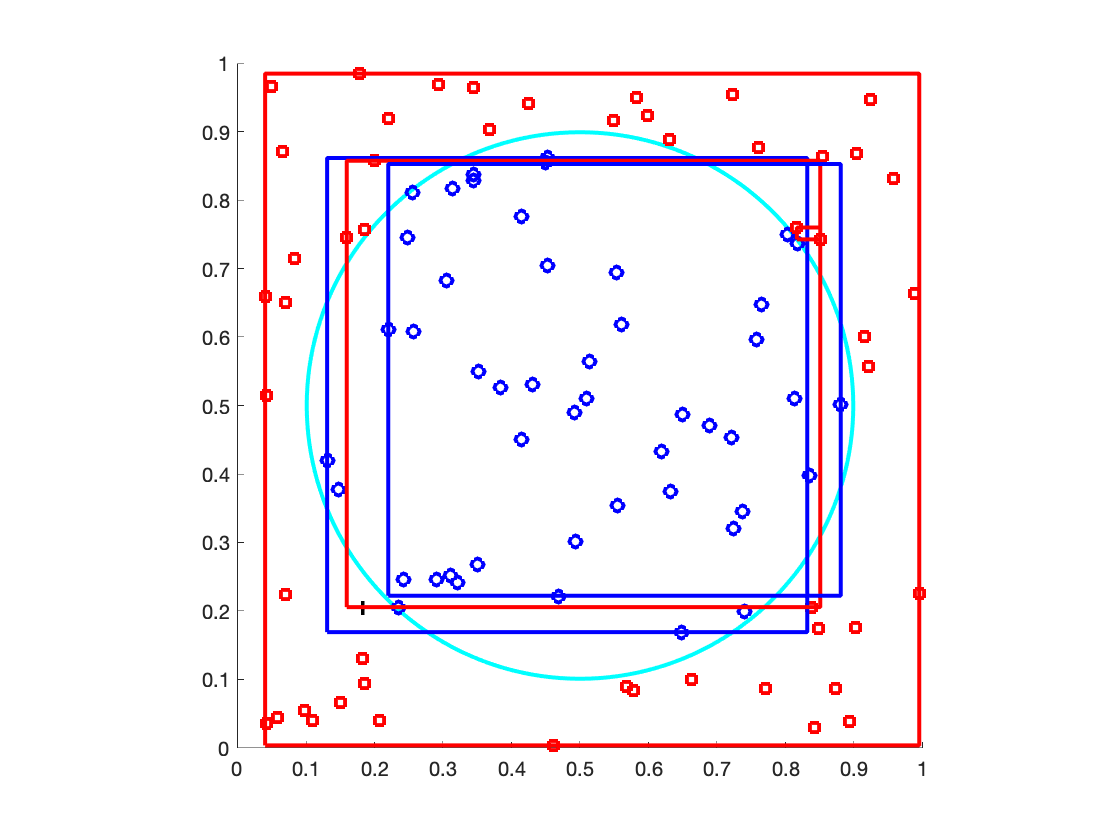

[C, w_code, w_out] = artmap_train(data_x, data_y,2,1,1 );

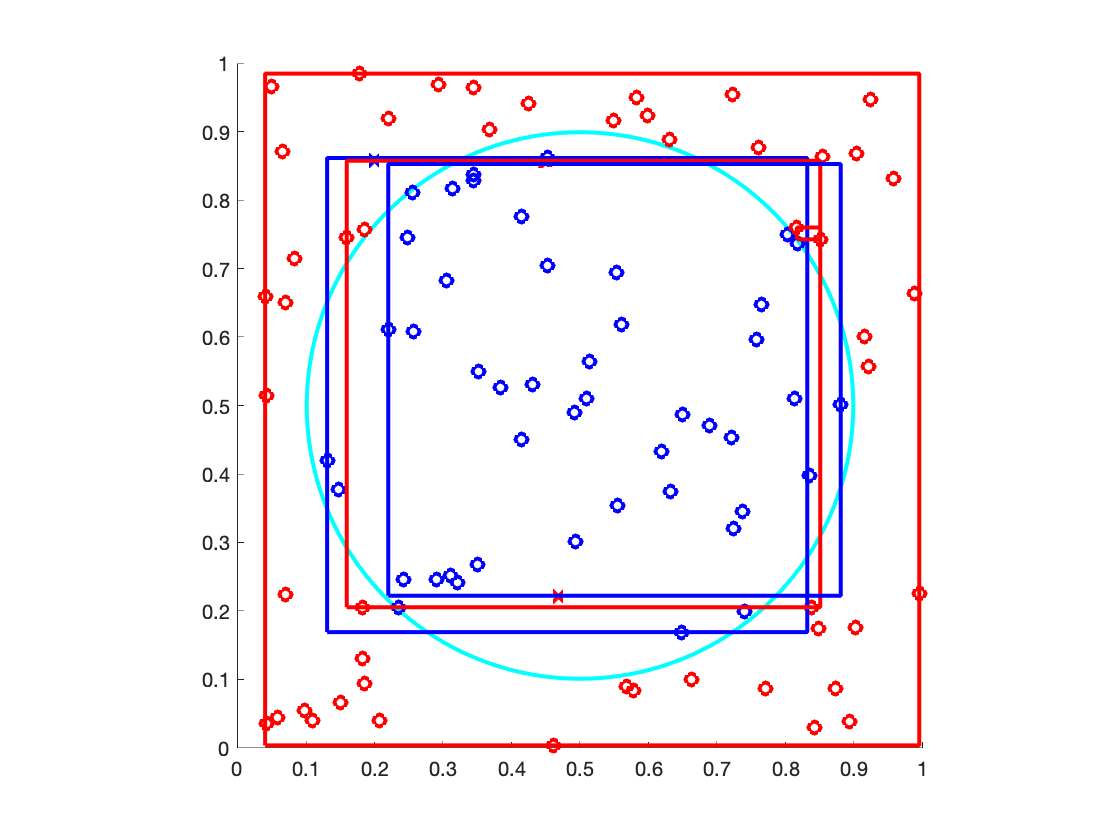

ypred_h =      0     0     0     1     0     0     0     1     0     0     0     0     1     1     1     0     0     0     1     0     1     1     1     1     1     1     1     1     0     1     1     1     0     1     0     0     0     0     1     1     1     1     0     1     1     0     0     0     1     0
     0     1     1     0     1     1     1     0     1     1     1     1     0     0     0     1     1     1     0     1     0     0     0     0     0     0     0     0     1     0     0     0     1     0     1     1     1     1     0     0     0     0     1     0     0     1     1     1     0     1


ypred_h = artmap_test_wta(C, w_code, w_out, data_x, data_y, 2, 0, 1)

Now, we are really increasing the epochs. This looks similar to the original 3 epochs at a beta of .5, but we are more established now. We have a pretty high accuracy with very few misses. This is an improvement by all means, however we are slower on training. This appears to be our best plot with the fewst misses. 

Beta: .25 | Epoch: 10

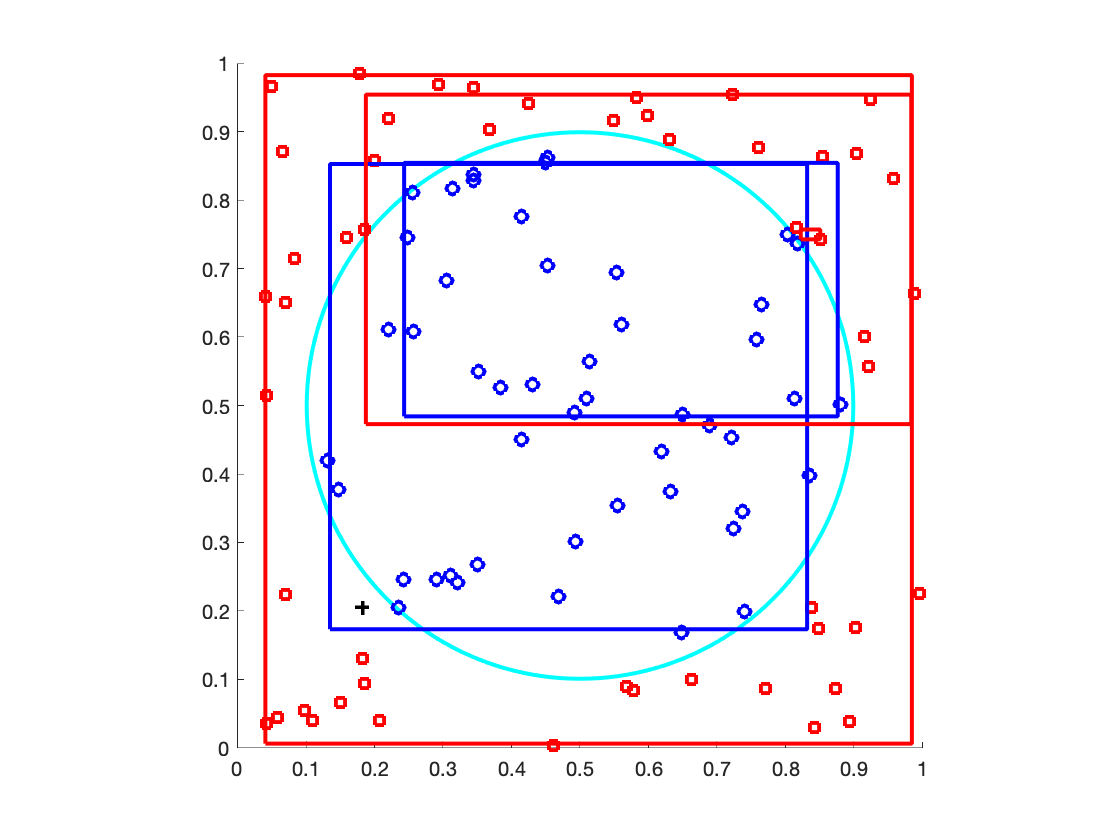

[C, w_code, w_out] = artmap_train(data_x, data_y,2,1,1 );

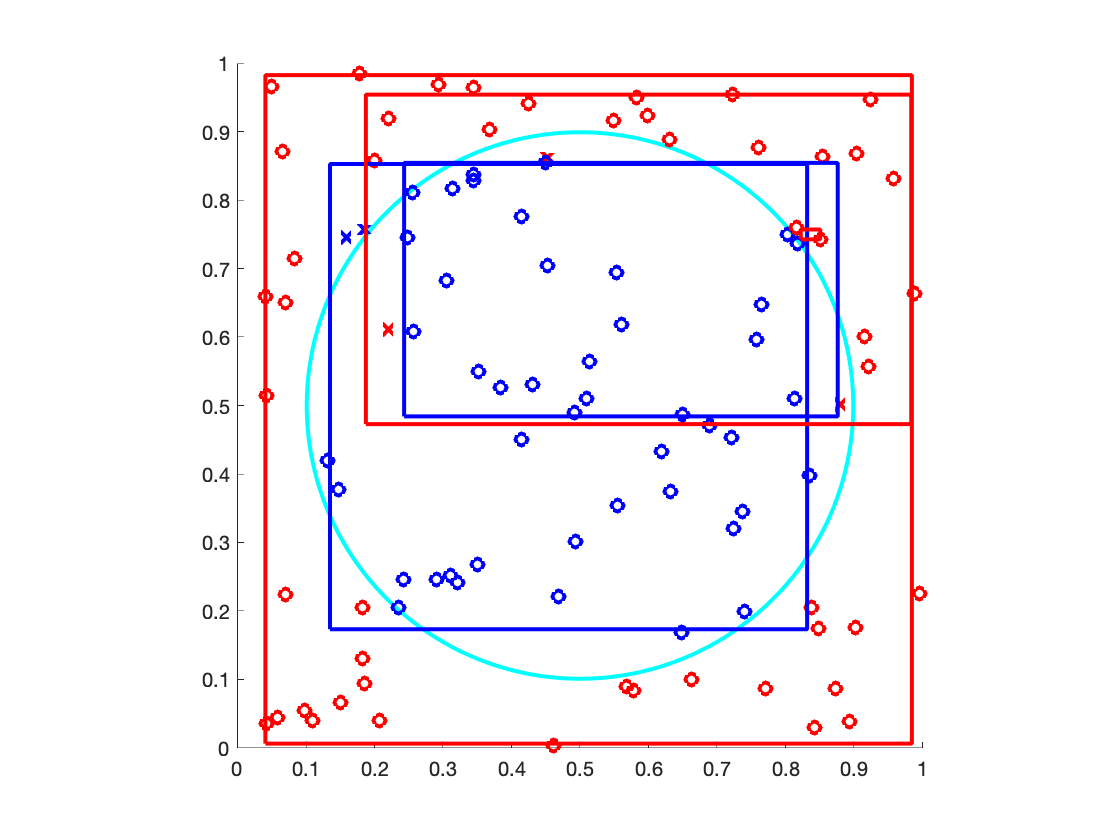

ypred_h =      0     0     0     1     0     0     0     0     0     0     0     0     1     1     1     0     0     0     1     0     1     1     1     1     1     1     1     0     0     1     1     1     0     0     0     1     1     0     1     1     1     1     0     1     1     0     1     0     1     0
     0     1     1     0     1     1     1     1     1     1     1     1     0     0     0     1     1     1     0     1     0     0     0     0     0     0     0     1     1     0     0     0     1     1     1     0     0     1     0     0     0     0     1     0     0     1     0     1     0     1


ypred_h = artmap_test_wta(C, w_code, w_out, data_x, data_y, 2, 0, 1)

This is a curious plot because of the placement of the boxes. It is interesting to pay attention to the number of category boxes, two of each so the slower learning rate might be learning more granular categories. In fact, it looks like there may be a small category growin on the far right to classify the two points on the edge of the ground truth circle as squares, correctly. This is overall a great plot that has extrememly high accuracy. Slow learning rate with more epochs is shaping up to be a solid way to train.

Beta: .01 | Epoch 10

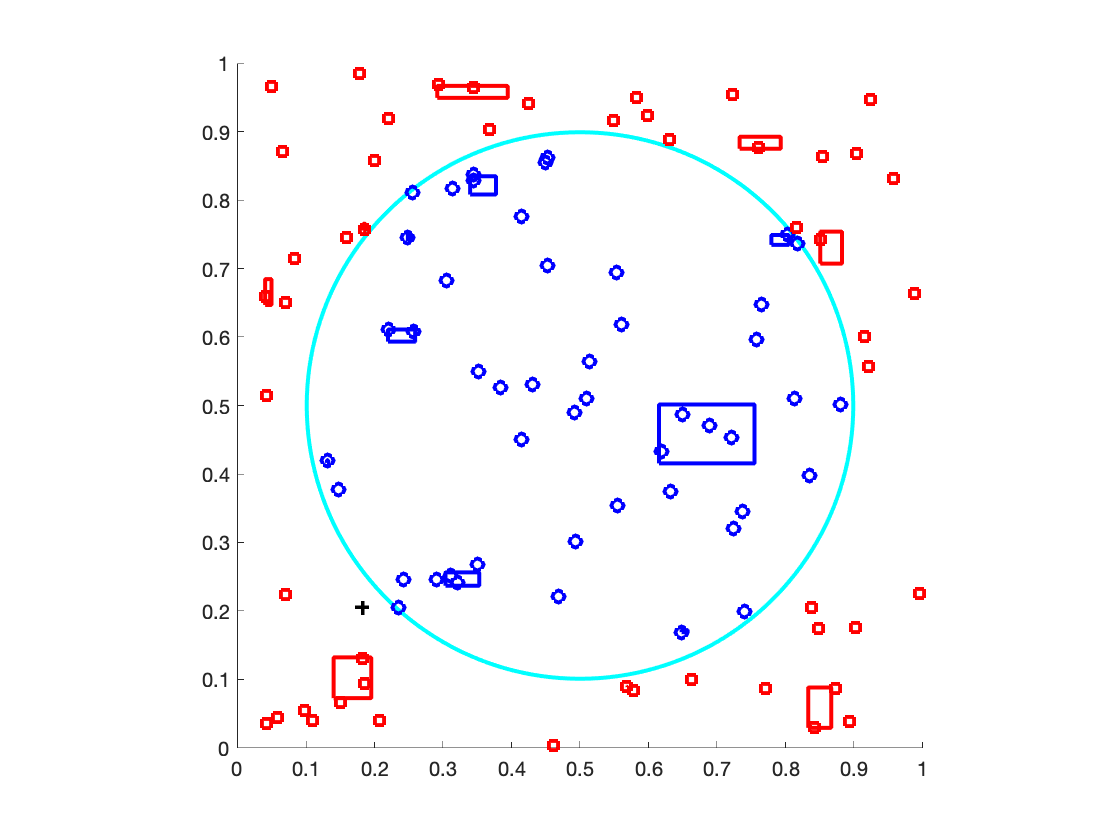

[C, w_code, w_out] = artmap_train(data_x, data_y,2,1,1 );

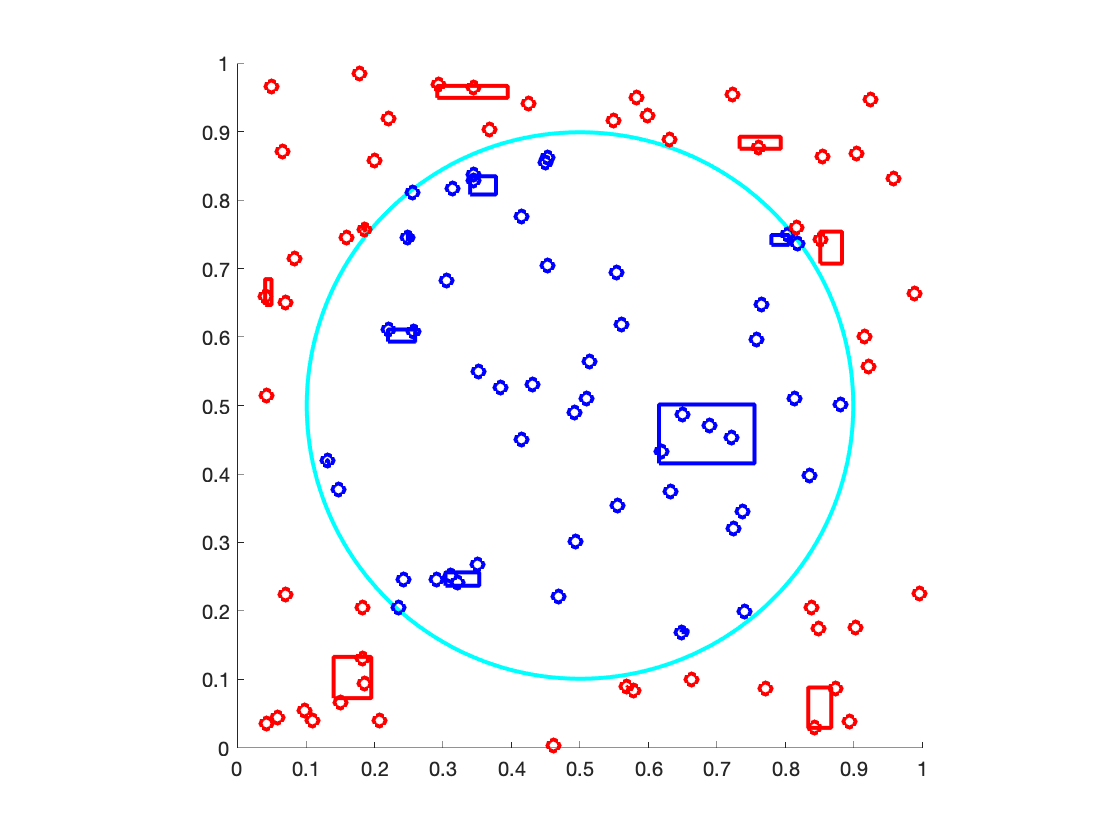

ypred_h =      0     0     0     1     0     0     0     0     0     0     0     0     1     1     1     0     0     0     1     0     1     1     1     1     1     1     1     1     0     1     1     1     0     1     0     0     0     0     1     1     1     1     0     1     1     0     1     0     1     0
     0     1     1     0     1     1     1     1     1     1     1     1     0     0     0     1     1     1     0     1     0     0     0     0     0     0     0     0     1     0     0     0     1     0     1     1     1     1     0     0     0     0     1     0     0     1     0     1     0     1


ypred_h = artmap_test_wta(C, w_code, w_out, data_x, data_y, 2, 0, 1)

We are making a bit of progress with more boxes and a bit more growth however still this does not run long enough.

Beta: .01 | Epoch 50

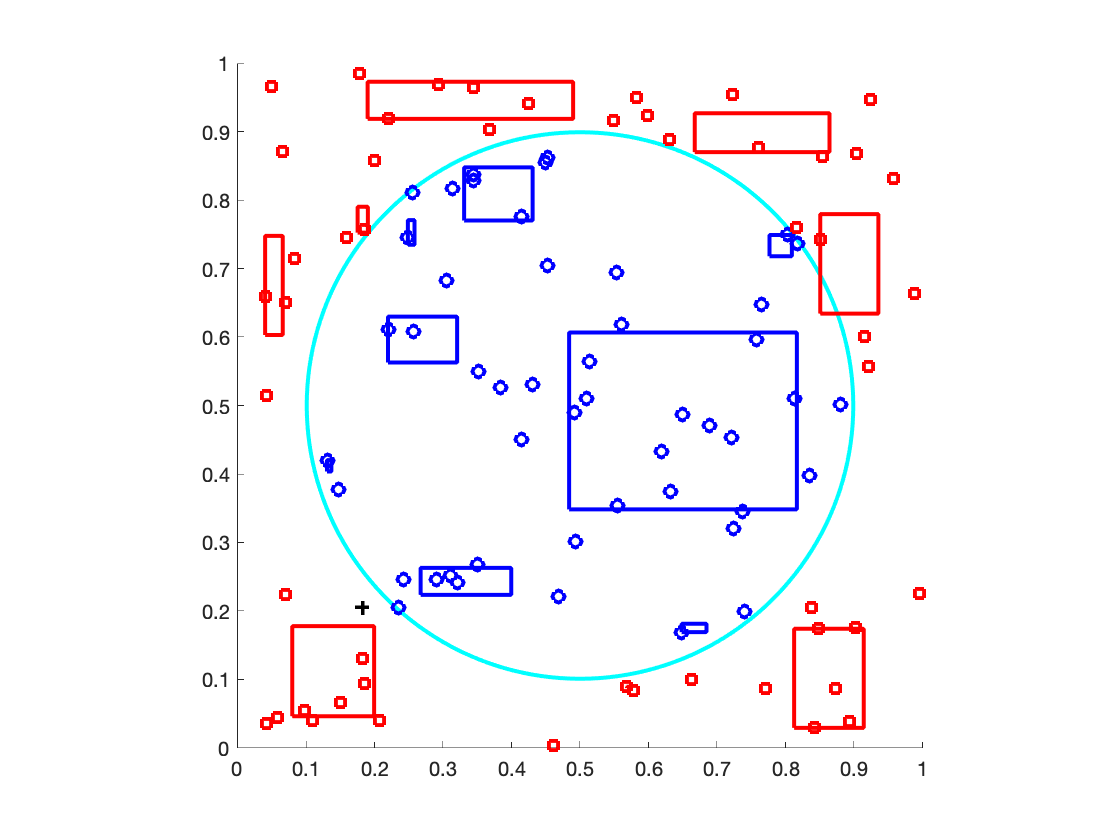

[C, w_code, w_out] = artmap_train(data_x, data_y,2,1,1 );

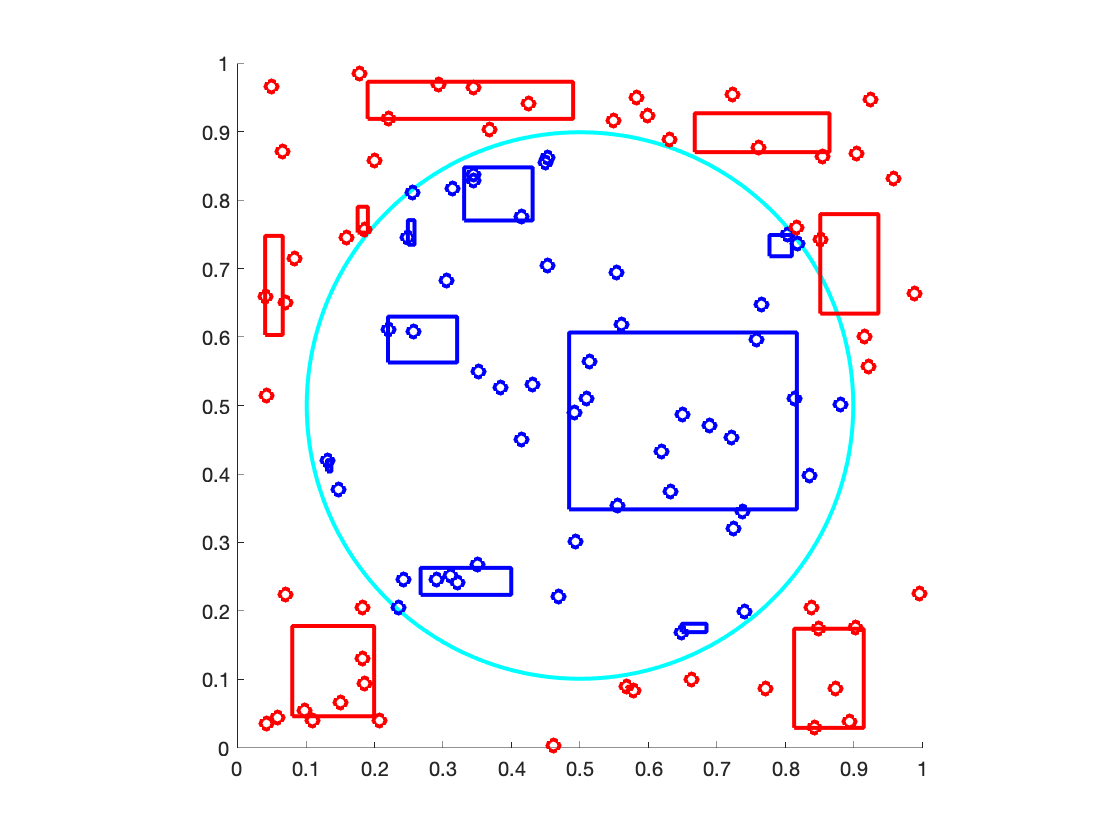

ypred_h =      0     0     0     1     0     0     0     0     0     0     0     0     1     1     1     0     0     0     1     0     1     1     1     1     1     1     1     1     0     1     1     1     0     1     0     0     0     0     1     1     1     1     0     1     1     0     1     0     1     0
     0     1     1     0     1     1     1     1     1     1     1     1     0     0     0     1     1     1     0     1     0     0     0     0     0     0     0     0     1     0     0     0     1     0     1     1     1     1     0     0     0     0     1     0     0     1     0     1     0     1


ypred_h = artmap_test_wta(C, w_code, w_out, data_x, data_y, 2, 0, 1)

In an attempt to make the growth show more, I ran this with 50 epochs. This is looking more accurate, many of the datapoints are placed within a category box. We have far more category boxes than in other plots with smaller numbers of epochs and higher learning rates. This is probably a byproduct of being more cautious and generating more granular categories. Overall, this will be more accurate in the end. 